imageFolder = fullfile("修正")

imageFolder = "修正"

imds = imageDatastore(imageFolder,"IncludeSubfolders",true)

imds =   ImageDatastore のプロパティ:

                       Files: {
                              'G:\segmentation\修正\easy2.jpg';
                              'G:\segmentation\修正\easy24.jpg';
                              'G:\segmentation\修正\easy33.jpg'
                               ... and 11 more
                              }
                     Folders: {
                              'G:\segmentation\修正'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


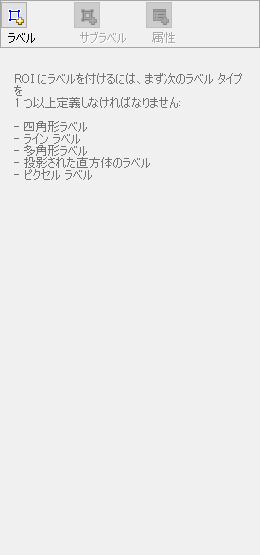

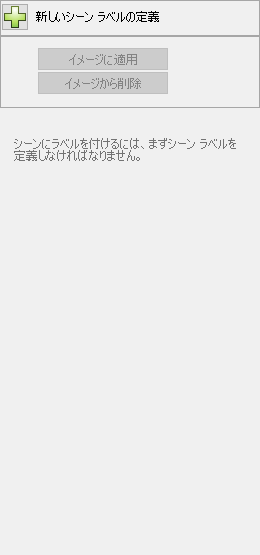

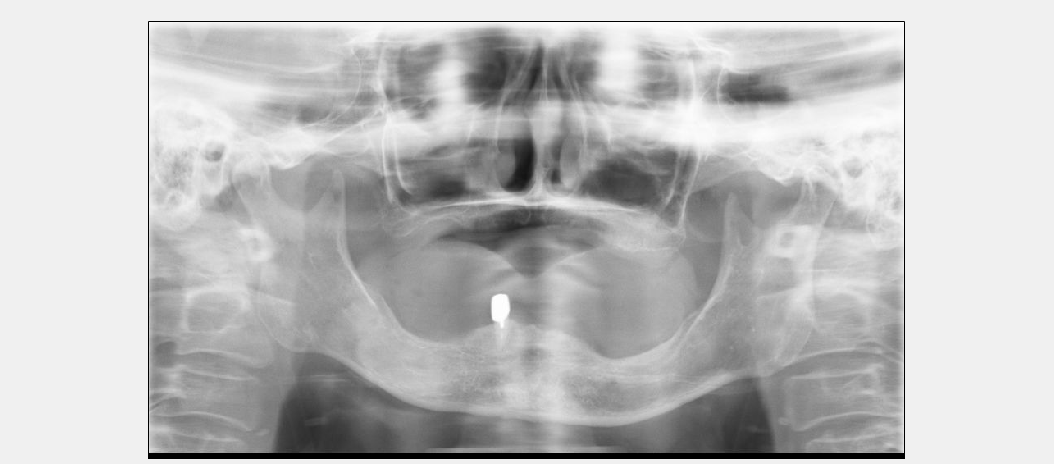

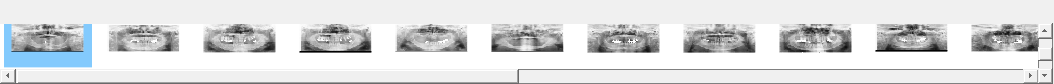

imageLabeler(imds)

list = dir("PixelLabelData/*.png");
len = length(list);
for i = 1: len
    name = list(i).name;
    img=imread(strcat("PixelLabelData/",name));
    img = uint8(img * 255);
    imwrite(img,strcat("処理済み/",name))
end